# Sample 10-2

## 冗長変換

分析問題

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Redundant transforms

Analysis problem

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

## フィルタ係数設定と入力信号の生成

(Setting of filter Coefs. and generation of input)

% Coefficients of analysis filters
gamma = 0.5;
delta = 1 - gamma;

% Input signal
u = [ 0 3 1 3 1 5 3 0 ]; % Set to even length

### 並列フィルタバンク実装

(Parallel filter bank implementation)

分析フィルタバンクをデシメータで、合成フィルタバンクをインタポレータで実装

% # of channels
nChs = 2;

% Analysis filters
h0 = [ gamma  delta ];
h1 = [ gamma -delta ];

% Synthesis filters
f0 = [  1 1 ]/2; 
f1 = [ -1 1 ]/2;

% Analysis process
s0 = conv(h0,u);
s1 = conv(h1,u);

% Synthesis process
v0 = conv(f0,s0);
v1 = conv(f1,s1);
v = v0 + v1;

% Energy of subband Coefs.
disp(['||s||_2^2 = ' num2str(norm([s0(:);s1(:)],2)^2)])

||s||_2^2 = 54


## 信号表示

(Signal display)

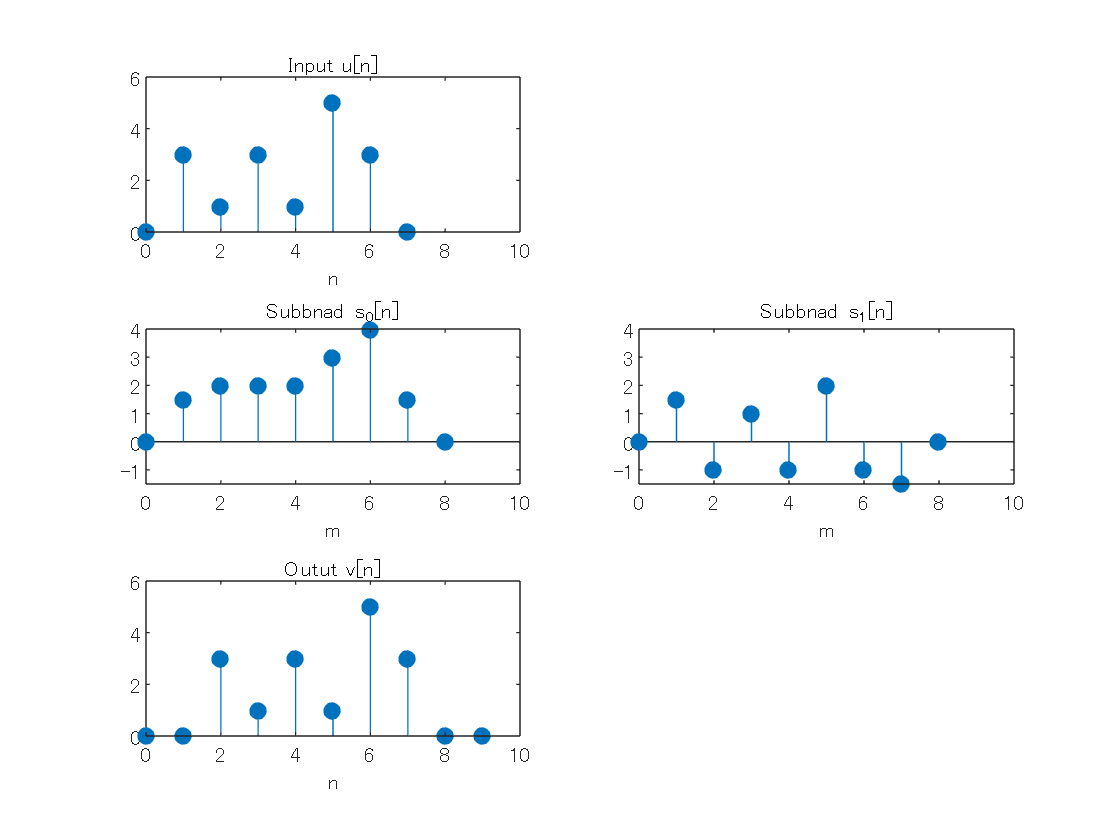

figure(1)
% Input
subplot(3,2,1)
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

% Subband 0
subplot(3,2,3)
stem(0:length(s0)-1,s0,'filled')
title('Subbnad s_0[n]')
xlabel('m')
ax = gca;
ax.XLim =[ 0 length(v)];
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Subband 1
subplot(3,2,4)
stem(0:length(s1)-1,s1,'filled')
title('Subbnad s_1[n]')
xlabel('m')
ax = gca;
ax.XLim =[ 0 length(v)];
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Output
subplot(3,2,5)
stem(0:length(v)-1,v,'filled')
title('Outut v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];


% MSE 評価
mymse = @(x,y) mean((x(:)-y(:)).^2);
disp(['MSE = ', num2str(mymse(u, v(2:end-1)))]);

MSE = 0


### インパルス応答

(Impluse responses of synthesis filters)

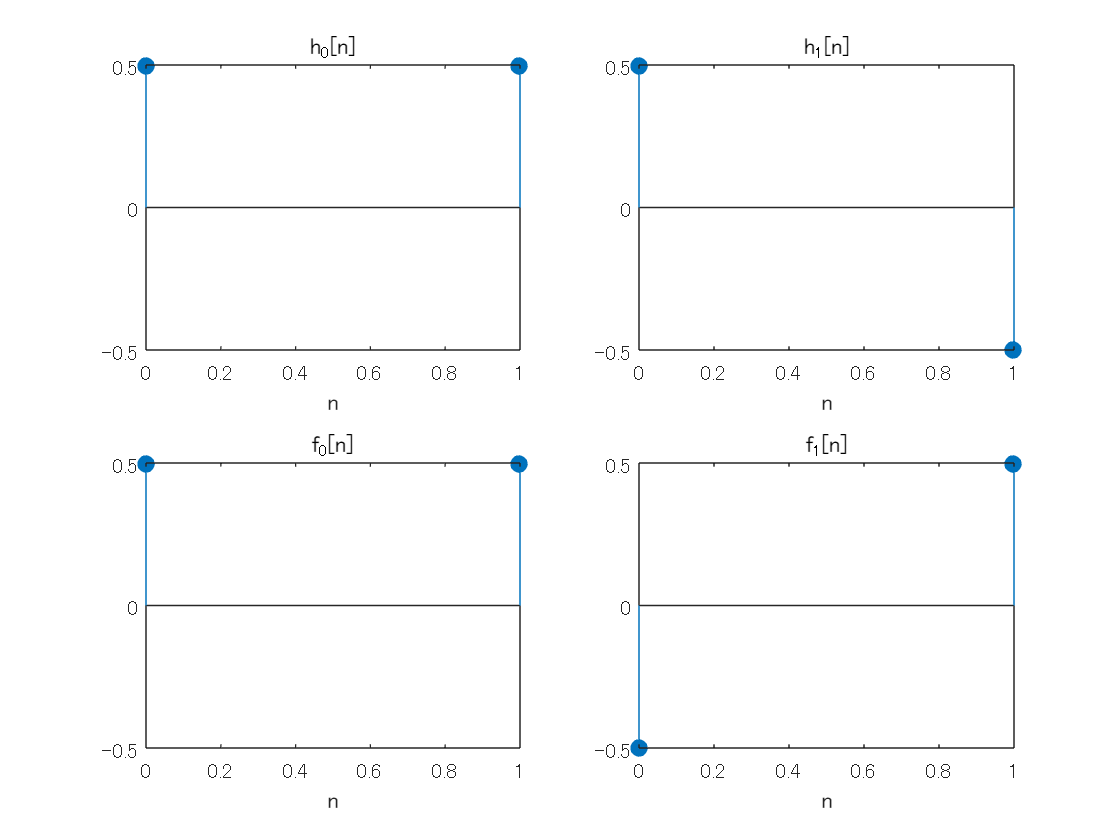

figure(2)

% Low-pass analysis filter
subplot(2,2,1)
stem(0:length(h0)-1,h0,'filled')
title('h_0[n]')
xlabel('n')
ax = gca;
ax.YLim =[ min([h0(:);h1(:)]) max([h0(:);h1(:)]) ];

% High-pass analysis filter
subplot(2,2,2)
stem(0:length(h1)-1,h1,'filled')
title('h_1[n]')
xlabel('n')
ax = gca;
ax.YLim =[ min([h0(:);h1(:)]) max([h0(:);h1(:)]) ];

% Low-pass synthesis filter
subplot(2,2,3)
stem(0:length(f0)-1,f0,'filled')
title('f_0[n]')
xlabel('n')
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

% High-pass synthesis filter
subplot(2,2,4)
stem(0:length(f1)-1,f1,'filled')
title('f_1[n]')
xlabel('n')
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

### 周波数応答

(Frequency responses)

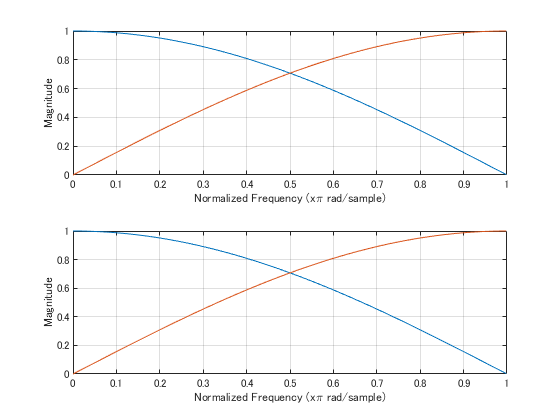

figure(3)
fftPoints = 512;

% Analysis filters
subplot(2,1,1)
H = zeros(fftPoints,nChs);
% Low-pass filter
[H(:,1),W] = freqz(h0,1,fftPoints);
% High-pass filter
H(:,2)     = freqz(h1,1,fftPoints);
plot(W/pi,abs(H)) %20*log10(abs(F)))
%axis([0 1 0 1]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
grid on

% Synthesis filters
subplot(2,1,2)
F = zeros(fftPoints,nChs);
% Low-pass filter
[F(:,1),W] = freqz(f0,1,fftPoints);
% High-pass filter
F(:,2)     = freqz(f1,1,fftPoints);
plot(W/pi,abs(F)) %20*log10(abs(F)))
axis([0 1 0 1]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
grid on

### ポリフェーズ行列実装（PPMATRIXオブジェクト利用）

(Polyphase matrix implemenation with PPMATRIX object)

フィルタバンクをポリフェーズフィルタに分解して、ポリフェーズ行列として実装 (Decompose the filter bank into polyphase filters and implement them in a polyphase matrix.)

        
$$\mathbf{E}(z)=\left(\begin{array}{c}  h_0[0] \\ h_1[0]\end{array}\right)
+\left(\begin{array}{c}  h_0[1] \\ h_1[1]\end{array}\right)z^{-1}
=\left(\begin{array}{cc}  h_0[0]+h_0[1]z^{-1}  \\ h_1[0]+h_1[1]z^{-1}\end{array}\right)$$


        
$$\mathbf{R}(z)=\left(\begin{array}{cc}  f_0[0] &f_1[0]\end{array}\right)
+\left(\begin{array}{cc}  f_0[1] &f_1[1]\end{array}\right)z^{-1}
=\left(\begin{array}{cc}  f_0[0]+f_0[1]z^{-1} &f_1[0]+f_1[1]z^{-1} \end{array}\right)$$


% Type-I polyphase filters of analyzer
e00 = h0(1:end);
e10 = h1(1:end);

% Type-II polyphase filters of synthesizer
r00 = f0(1:end);
r01 = f1(1:end);

ポリフェーズ行列演算が簡便となるよう以下のクラスを定義した。インスタンス化の際、3番目の添え字が遅延を示す3次元配列を渡す。(In order to make polyphase matrix operations easier, the following classe is defined. At instantiation, plase pass a three-dimensional array where the third subscript indicates a delay.)

- PPMATRIX： Polyphase Matrix Class (originally from saivdr.dictionary.utility.PolyPhaseMatrix1D in [SaivDr package](https://github.com/msiplab/SaivDr) )

分析合成処理 (Analysis and synthesis process)

import msip.ppmatrix
% Polyphase matrix of analysis bank
e00 = reshape(e00,1,1,length(e00));
e10 = reshape(e10,1,1,length(e10));
E = ppmatrix(cat(1,e00,e10))

E = [
	0.5 + 0.5*z^(-1);
	0.5 - 0.5*z^(-1)
]


% Polyphase matrix of synthesis bank
r00 = reshape(r00,1,1,length(r00));
r01 = reshape(r01,1,1,length(r01));
R = ppmatrix(cat(2,r00,r01))

R = [
	0.5 + 0.5*z^(-1),	-0.5 + 0.5*z^(-1)
]


完全再構成条件の確認 (Confirmation of perfect reconstruction)

        
$$\mathbf{R}(z)\mathbf{E}(z)=(\mathbf{R}_0 +\mathbf{R}_1 z^{-1} )(\mathbf{E}_0 + \mathbf{E}_1 z^{-1} )=\mathbf{R}_0 \mathbf{E}_0 + (\mathbf{R}_1 \mathbf{E}_0 +\mathbf{R}_0 \mathbf{E}_1 )z^{-1}+\mathbf{R}_1\mathbf{E}_1 z^{-2}=z^{-1}\mathbf{I} $$
 

disp(R*E)

[
	z^(-1)
]



% Define delaychain
clear delaychain
delaychain(1,1,1) = 1;
delaychain = ppmatrix(delaychain)

delaychain = [
	1
]


% Z-transform of input
u = ppmatrix(reshape(u,1,1,length(u)));
disp(u)

[
	3*z^(-1) + z^(-2) + 3*z^(-3) + z^(-4) + 5*z^(-5) + 3*z^(-6)
]



% Polyphase decomposition of input
x = delaychain*u;
disp(x)

[
	3*z^(-1) + z^(-2) + 3*z^(-3) + z^(-4) + 5*z^(-5) + 3*z^(-6)
]



% Analysis process w/ the polyphase matrix
s = E*x;
disp(s)

[
	1.5*z^(-1) + 2*z^(-2) + 2*z^(-3) + 2*z^(-4) + 3*z^(-5) + 4*z^(-6) + 1.5*z^(-7);
	1.5*z^(-1) - z^(-2) + z^(-3) - z^(-4) + 2*z^(-5) - z^(-6) - 1.5*z^(-7)
]



% Synthesis process w/ the polyphase matrix
y = R*s;
disp(y)

[
	3*z^(-2) + z^(-3) + 3*z^(-4) + z^(-5) + 5*z^(-6) + 3*z^(-7)
]



% Parallel/Serial conversion
v = delaychain.'*y;
disp(v)

[
	3*z^(-2) + z^(-3) + 3*z^(-4) + z^(-5) + 5*z^(-6) + 3*z^(-7)
]



disp(squeeze(double(v)).')

     0     0     3     1     3     1     5     3     0     0



© Copyright, Shogo MURAMATSU, All rights reserved.